Task 1B: Digitization


clear
clc

% digitize mycelial image data
image = imread('cswk1_mycelium_curve.png');   % my mycelial imput data

% Capture 50 data points using ginput function
[x_points, y_points] = ginput(50);  

% Fixing ginput point data:
img_height = size(image,1);
img_width  = size(image,2);

% Fix x_points
x_fix = (x_points - min(x_points)) / (max(x_points) - min(x_points));
x_fix = x_fix * (2*pi);

% Fix y_points
y_fix = (max(y_points) - y_points) / (max(y_points) - min(y_points));
y_fix = y_fix * 20;  % y maximum value = 20 to keep the graph shape accurate

% plot to find where to separate the two parts of the graph
fig1 = figure;
plot(x_fix,y_fix,'b-')
title('Initial mycelial datapoints')
xlabel('x')
ylabel('f(x)')
ylim([0 max(y_fix)+3])




Task 1B & Task 1C: Fitting of Polynomial Datapoints to Functions:

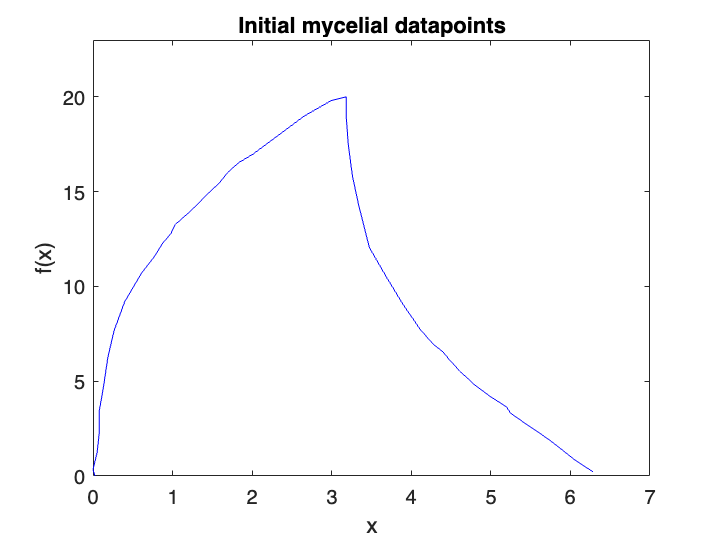


% separate the graph's two curves into x and y values
xpts_curve1 = x_fix(1:28);
ypts_curve1 = y_fix(1:28);

xpts_curve2 = x_fix(30:end);
ypts_curve2 = y_fix(30:end);

% fit polynomials
poly_curve1 = polyfit(xpts_curve1,ypts_curve1,2);
poly_curve2 = polyfit(xpts_curve2,ypts_curve2,2);

% round and simplify polyfit values
poly_curve1_round = [-2.2 12.2 2.4];
poly_curve2_round = [1.9 -23.5 74.4];     % y-intercept is increased for a better fit


% fit a more accurate curve based on the initial ginput data
pts = 50;        % enough data points for a smooth graph

% curve one fitting
X_c1  = linspace(min(xpts_curve1), max(xpts_curve1), pts/2);
Y_c1  = polyval(poly_curve1_round, X_c1);

% curve two fitting
X_c2 = linspace(min(xpts_curve2),2*pi,pts/2);
Y_c2 = polyval(poly_curve2_round, X_c2);

% reform data into datapoints
X = [X_c1 X_c2];
Y = [Y_c1 Y_c2];


% Converting Variable to a text file/Excel spreadsheet
T = table(X', Y', 'VariableNames', {'X','Y'});
writetable(T, 'Mycelium_Impulse_Data1.xlsx');


% plot fixed mycelial curve:
fig2 = figure;
plot(X, Y, 'b-')
title('Fitted mycelial datapoints')
xlabel('x')
ylabel('f(x)')
xlim([0 2*pi])
ylim([0 max(Y)+2])


% Save figures:
saveas(fig1,'Initial mycelial datapoints','png')

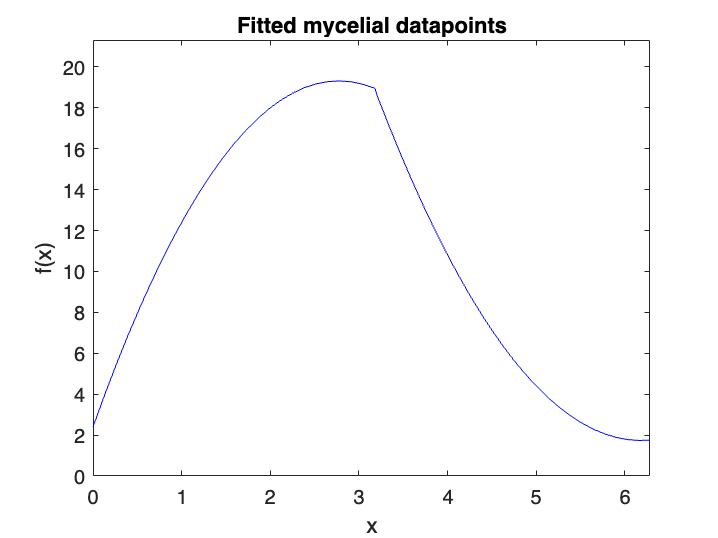

saveas(fig2,'Fitted mycelial datapoints','png' )

Task 1C: Modelling


clear
clc

poly1 = [-2.2 12.2 2.4];        % curve 1 polynomial, interval 0 to π
poly2 = [1.9 -23.5 74.4];       % curve 2 polynomial, interval π to 2π

% Define the polynomials as a function
fun1 = @(x) poly1(1).*x.^2+poly1(2).*x+poly1(3);
fun2 = @(x) poly2(1).*x.^2+poly2(2).*x+poly2(3);


% calculating the 5, 8 and 20 term Fourier series
term_5 = 5;
[a0_5,an_5,bn_5] = fourier_coefficients(term_5,fun1,fun2);

term_8 = 8;
[a0_8,an_8,bn_8] = fourier_coefficients(term_8,fun1,fun2);

term_20 = 20;
[a0_20,an_20,bn_20] = fourier_coefficients(term_20,fun1,fun2);

% evaluate over one period (0 to 2π)
x = linspace(0, 2*pi, 1000);

FS5 = fourier_series(x,a0_5, an_5, bn_5);
FS8 = fourier_series(x,a0_8,an_8,bn_8);
FS20 = fourier_series(x,a0_20,an_20,bn_20);

% compare 5, 8 and 20 term series
fig3 = figure;
plot(X, Y, 'k-','LineWidth',1)
hold on
plot(x,FS5,'g','LineWidth',1)
plot(x,FS8,'b','LineWidth',1)
plot(x, FS20,'r','LineWidth',1)

legend('Source curve','5-terms','8-terms','20-terms')
xlabel('x')
ylabel('f(x)')
xlim([0 2*pi])
title('Fourier Series Approximation (5, 8 and 20 terms)')


Task 1D

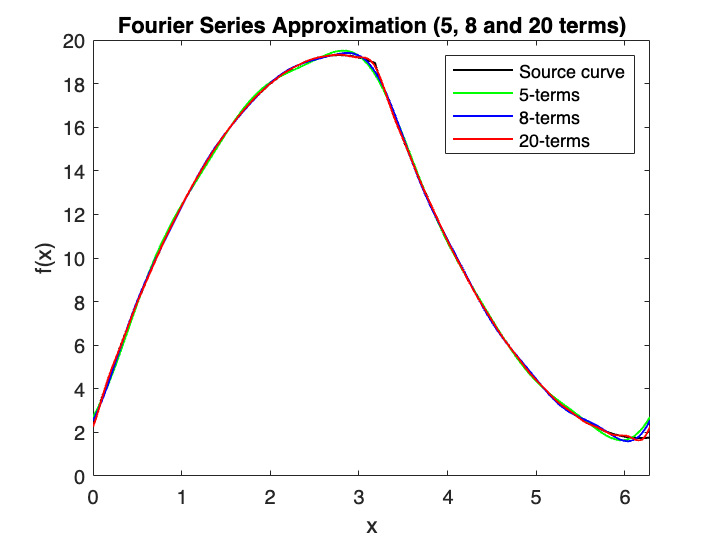


% Fourier approximation from 0 to 8pi
x_8pi = linspace(0,8*pi,4000);
y_8pi = fourier_series(mod(x_8pi,2*pi),a0_8, an_8,bn_8);

fig4 = figure;
plot(x_8pi, y_8pi, 'b','LineWidth', 1)
xlabel('x')
ylabel('f(x)')
title('Repeated 8-Term Fourier Series ( 0 to 8pi )')
xlim([0 8*pi])

% Save figures:
saveas(fig3,'Comparison_Terms','png')

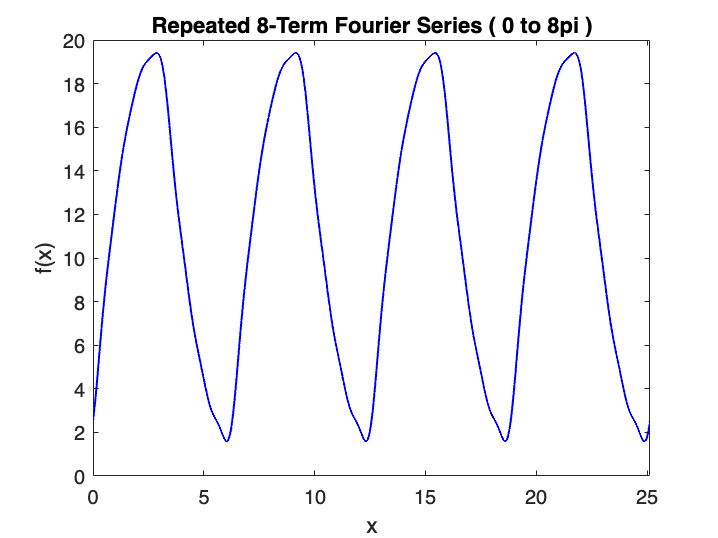

saveas(fig4,'Fourier_to_8pi','png' )

Task 2A


clear
clc

% import GNSS data (data in meters)
data_GNSS = importdata("jeddah_tower_heights_gnss.xlsx")

data_GNSS = 1.0e+03 *

    1.0001
    0.9997
    0.9999
    1.0002
    1.0003
    0.9997
    1.0004
    1.0002
    1.0000
    0.9999



% clean data to a resolution of 1mm (3 d.p.)
data_round = round(data_GNSS,3);

% initial innacurate standard deviation and mean (for calculating outliers)
StandDiv_in = std(data_round,1);      % sample standard div
Mean_in = mean(data_round);           % sample mean

% cleaning outliers
lower_bound = Mean_in-3*StandDiv_in;
upper_bound = Mean_in+3*StandDiv_in;

%% Remove outliers for 3 standard div from mean
data_clean = data_round((data_round >= lower_bound) & (data_round <= upper_bound));

% values for sample mean, standard div and standard error (GNSS)
length_GNSS = length(data_clean);

sample_mean_GNSS = mean(data_clean)                % sample mean          

sample_mean_GNSS = 999.9858

StandDiv_GNSS = std(data_clean, 1)                 % sample standard deviation

StandDiv_GNSS = 0.2999

StandError_GNSS = StandDiv_GNSS/sqrt(length_GNSS)       % standard error of the sample mean

StandError_GNSS = 0.0247

Task 2B

clear
clc



% define number of intervals
int_no = 5;

% create categories
intervals = linspace(min(data_clean),max(data_clean),int_no+1);

% Observed Frequencies Oi
observed_freq = histcounts(data_clean, intervals);

% for loop for Expected frequencies under the assumption that the data is
% normally distributed
expected_freq = zeros(1,int_no);
for i = 1:int_no
    prob_Ei = normcdf(intervals(i+1), sample_mean_GNSS, StandDiv_GNSS) - normcdf(intervals(i), sample_mean_GNSS, StandDiv_GNSS);
    expected_freq(i) = length*prob_Ei;    % Expectation = Ei = xi * pi
end

% chi-squared statistic calculation
chi_val = ((observed_freq - expected_freq).^2)./expected_freq;
chi_statistic = sum(chi_val);

% Chi goodness of fit hypothesis conclusion
critical_value = 5.99    % from statistics table

critical_value = 5.9900

decision = "Fail to reject H0"

Task 2C

clear
clc

% import geometric data (data in meters)
data_geo = importdata("jeddah_tower_heights_geometric.xlsx")

data_geo = 1.0e+03 *

    1.0008
    1.0017
    1.0006
    1.0020
    1.0014
    1.0042
    1.0031
    0.9995
    1.0024
    1.0006



% clean data to a resolution of 1mm (3 d.p.)
data_round_geo = round(data_geo,3);

length_geo = length(data_round_geo);

% calculating sample mean.
sample_mean_geo = mean(data_round_geo);

% sample standard deviation
Stand_Div_geo = std(data_round_geo, 1);

% sample standard error of the sample mean 
StandError_geo = Stand_Div_geo/sqrt(length_geo);

% remove outliers (+ or - 3 stand divs from from the samaple mean)
lower_limit = sample_mean_geo - 3 * Stand_Div_geo;
upper_limit = sample_mean_geo + 3 * Stand_Div_geo;
clean_data = data_round_geo((data_round_geo >= lower_limit) & (data_round_geo <= upper_limit));



Task 2D

clear 
clc

% T-TEST:

%Imput values from previous tasks: (1 = GNSS data and 2 = geometric data)

samp_mean1 = 999.986;
samp_mean2 = 1001.939;
% mu 1 - mu2 is 0 as the population means are the same
mu1_mu2 = 0

mu1_mu2 = 0

% sample standard deviations
StandDiv1 = 0.300;
StandDiv2 = 1.018;
% sample sizes
size1 = 148

size1 = 148

size2 = 31

size2 = 31


% t-statistic
t_statistic = ((samp_mean1 - samp_mean2)- mu1_mu2)/sqrt((StandDiv1^2)/size1 +(StandDiv2^2)/size2);

% critical value
alpha = 0.05;
crit_val_t = 2.042  % from t-test statistics table 

crit_val_t = 2.0420






% F-TEST

F_statistic = (StandDiv2^2)/(StandDiv1^2)

F_statistic = 11.5147

crit_val_F = 1.55  % from F-test statistics table 

crit_val_F = 1.5500

Task 1C functions:

function [a0, an, bn] = fourier_coefficients(terms, fun1, fun2)

    a0_curve1  = integral(@(x) fun1(x), 0, pi);
    a0_curve2 = integral(@(x) fun2(x), pi, 2*pi);
    a0 = (1/pi) * (a0_curve1 + a0_curve2);

    an = zeros(1, terms);
    bn = zeros(1, terms);

    for n = 1:terms
        an_curve1  = integral(@(x) fun1(x).*cos(n*x), 0, pi);
        an_curve2 = integral(@(x) fun2(x).*cos(n*x), pi, 2*pi);
        an(n) = (1/pi) * (an_curve1 + an_curve2);

        bn_curve1  = integral(@(x) fun1(x).*sin(n*x), 0, pi);
        bn_curve2 = integral(@(x) fun2(x).*sin(n*x), pi, 2*pi);
        bn(n) = (1/pi) * (bn_curve1 + bn_curve2);
    end
end

% Calculating Fourier series terms
function y = fourier_series(x, a0, an, bn)
    N = length(an);
    y = a0/2 * ones(size(x));

    for n = 1:N
        y = y + an(n)*cos(n*x) + bn(n)*sin(n*x);
    end
end


